close all
clear all
figure
axis equal off
hold on
running = 1;
n = 5;
numShips = 2;
ships={2,3,4}

ships = 1×3 cell array
    {[2]}    {[3]}    {[4]}


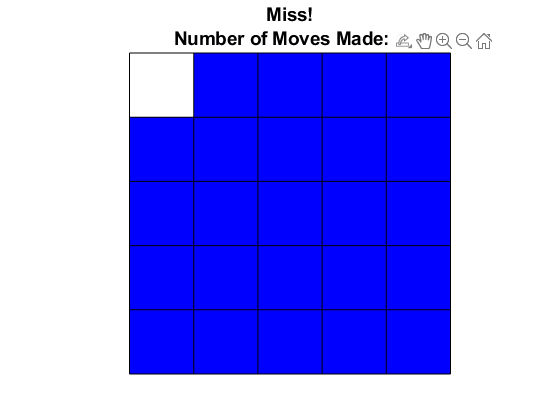

Index in position 1 exceeds array bounds. Index must not exceed 1.

%4x4 grid
for i=0:4
    for j=0:4
      fill([i i+1 i+1 i i],[j j j+1 j+1 j],'b')
    end
end
occ= zeros(5);
orientation = ceil(rand*2);
shipSize = 2;
%generate valid position
valid = 0;
while valid == 0
  if orientation == 2
     x= ceil(rand*(5-shipSize)); %generate random x position subtracting shipSize to
            %account for the ship occupying spaces beyond the boundaries of the
            %grid
     y= ceil(rand*2); %generate random y position
     if sum(occ(x:x+shipSize-1,y)~=0) == 0 %if entire length of squares is 0
        valid = 1;
     end
   elseif orientation == 1
      x= ceil(rand*5); %generate random x position subtracting shipSize to
            %account for the ship occupying spaces beyond the boundaries of the
            %grid
      y= ceil(rand*(5-shipSize)); %generate random y position
      if sum(occ(x,y:y+shipSize-1)~=0) == 0 %if entire length of squares is 0
           valid = 1;
      end
   end
end

    %now with valid position, place ship
 if orientation == 2
    for rem2=0:shipSize-1 %remaining squares of the ship
        occ(x+rem2,y) = 2; %edit
    end
 elseif orientation == 1
    for rem2=0:shipSize-1 %remaining squares of the ship
        occ(x,y+rem2) = 2; %edit
    end
 end
squares= zeros(5); % 0 means covered, 1 means uncovered
movesMade = 0; %initialise number of moves to be 0
titleText='Welcome to Battleship';
movesMadeText= sprintf('Number of Moves Made: %d',movesMade);
while running== 1
    title({titleText, movesMadeText}, 'FontSize', 14');
    [x,y] = ginput(1);
    X= ceil(x);
    Y= 5-ceil(y)+1;
    % user clicks on a square
    if X<=5 && Y <=5 && X>=1 && Y>=1 % ensures user clicks within playing field
        if squares(X,Y)==0 % square is covered, then uncover it
            squares(X,Y)= 1;
            movesMade = movesMade + 1;
            if occ(X,Y)~=0 % if square contains part of a ship
                titleText= 'Hit!';
                movesMadeText= sprintf('Number of Moves Made: %d',movesMade);
                ships{occ(X,Y),2}= ships{occ(X,Y),2} - 1; %decrease life of ship by 1
                fill ([X-1 X X X-1 X-1],[n-Y n-Y n-Y+1 n-Y+1 n-Y],'r');
            else % if square does not contain part of a ship
                titleText= 'Miss!';
                movesMadeText= sprintf('Number of Moves Made: %d',movesMade);
                fill ([X-1 X X X-1 X-1],[n-Y n-Y n-Y+1 n-Y+1 n-Y],'w');
            end
        elseif squares(X,Y)==1 % square is already uncovered, ask player to choose again
            titleText='Square already clicked on. Try again.';
            movesMadeText= sprintf('Number of Moves Made: %d',movesMade);
        end
    end
        %check if any ship has been sunk
    sumS= 0;
    for shipIndex= 1:numShips
        if ships{shipIndex,2}==0
            ships{shipIndex,2} = -1; %-1 means that ship has been sunk
            shipName= ships{shipIndex,1};
            titleText= sprintf('You sunk a %s',shipName);
            movesMadeText= sprintf('Number of Moves Made: %d',movesMade);
        end
        sumS= sumS + ships{shipIndex,2};
        if sumS== -1 * numShips %all ships have been sunk
            titleText= 'YOU WIN!';
            title({titleText, movesMadeText}, 'FontSize', 14');
            running = 0;
        end
    end
end